clc;clear;close all;

### **Load TPE1 data**

seismic_data{1} = importdata('1999_0925_235249_TAP013.txt');
seismic_data{2} = importdata('1999_0925_235249_TAP014.txt');
seismic_data{3} = importdata('1999_0925_235249_TAP020.txt');
seismic_data{4} = importdata('2000_0910_085446_TAP014.txt');
seismic_data{5} = importdata('2000_0910_085446_TAP020.txt');
seismic_data{6} = importdata('2001_0614_023525_TAP013.txt');
seismic_data{7} = importdata('2001_0614_023525_TAP020.txt');
seismic_data{8} = importdata('2002_0515_034605_TAP013.txt');
seismic_data{9} = importdata('2002_0515_034605_TAP020.txt');
seismic_data{10} = importdata('2004_1015_040850_TAP013.txt');
seismic_data{11} = importdata('2004_1015_040850_TAP014.txt');
seismic_data{12} = importdata('2004_1015_040850_TAP020.txt');
seismic_data{13} = importdata('2005_0305_190651_TAP014.txt');
seismic_data{14} = importdata('2005_0305_190651_TAP020.txt');
save TPE1.mat seismic_data;

### Plot seismic response spectrum

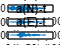

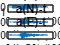

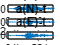

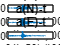

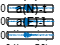

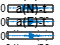

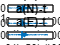

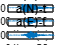

for i = 1:14
    t{i} = seismic_data{i}(:,1);
    a1{i} = seismic_data{i}(:,2);
    a2{i} = seismic_data{i}(:,3);
    a3{i} = seismic_data{i}(:,4);
    figure
    subplot(3,1,1)
    plot(t{i},a1{i}) 
    title('a(U)-t')
    xlabel('time(s)')
    ylabel('acceleration(m/s^2)')
    subplot(3,1,2)
    plot(t{i},a2{i})
    title('a(N)-t')
    xlabel('time(s)')
    ylabel('acceleration(m/s^2)')
    subplot(3,1,3)
    plot(t{i},a3{i}) 
    title('a(E)-t')
    xlabel('time(s)')
    ylabel('acceleration(m/s^2)')
end

### Assume structure data

T = (0.05:0.05:5)';
w = 2*pi./T;
m = 1;
dmp = 0.05;

### State-space, Plot PGA

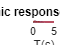

for i = 1:size(T,1)
    k = w(i)^2*m;
    c = 2*m*dmp*w(i);
    Ac = [0 1;-k/m -c/m];
    Bc = [0;-1];
    Cc = [eye(2);-k/m -c/m];
    Dc = zeros(3,1);
    sys_SDOF = ss(Ac,Bc,Cc,Dc);
    for j = 1:14
        y_SDOF = lsim(sys_SDOF,a3{1,j},t{1,j});
        y_SDOF2 = lsim(sys_SDOF,a2{1,j},t{1,j});
        PGA(i,j) = max(abs(y_SDOF(:,3)));
        PGA2(i,j) = max(abs(y_SDOF2(:,3)));
    end
end
figure
plot(T,PGA/9.81)
title('Seismic response spectrum')
xlabel('T(s)')
ylabel('PGA(NS)(g)')
hold on;

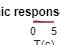

figure
plot(T,PGA2/9.81)
title('Seismic response spectrum')
xlabel('T(s)')
ylabel('PGA(WE)(g)')